motor6s_45=motor6s_45_210;

indici25 = find(motor6s_25);
[row25, col25, page25] = ind2sub(size(motor6s_25), indici25);

indici45 = find(motor6s_45);
[row45, col45, page45] = ind2sub(size(motor6s_45), indici45);

indici70 = find(motor6s_70);
[row70, col70, page70] = ind2sub(size(motor6s_70), indici70);

indici90 = find(motor6s_90);
[row90, col90, page90] = ind2sub(size(motor6s_90), indici90);
figure(5)
clf
plot3(0,0,0)
hold on

bnd = boundary([alpha_x_s(row25).',alpha_y_s(col25).',alpha_z_s(page25).'],0)

bnd =    659   726   731
   639   659   731
   511   272   101
   151   140    75
   736   723   737
   485   356   174
   737   735   736
   733   731   738
   471   659   639
   124   152    48


trisurf(bnd,alpha_x_s(row25),alpha_y_s(col25),alpha_z_s(page25),'Facecolor','red','FaceAlpha',1)

bnd = boundary([alpha_x_s(row45).',alpha_y_s(col45).',alpha_z_s(page45).'],0)

bnd =          851         836          63
         964         880         758
        1237         847         833
         971         798        1125
         664         458         177
        1125        1249        1150
        1305        1230        1225
         271         131         529
          63         836         798
        1302        1308        1297


trisurf(bnd,alpha_x_s(row45),alpha_y_s(col45),alpha_z_s(page45),'Facecolor','magenta','FaceAlpha',0.5)

bnd = boundary([alpha_x_s(row70).',alpha_y_s(col70).',alpha_z_s(page70).'],0)

bnd =          702         649         289
          36          98         289
        1701        1908        1841
         143         519         462
         775        1077        1105
        1341         649        1037
         377         188         143
         892         196        1209
         892         188         196
          19         403           2


trisurf(bnd,alpha_x_s(row70),alpha_y_s(col70),alpha_z_s(page70),'Facecolor','blue','FaceAlpha',0.1)

bnd = boundary([alpha_x_s(row90).',alpha_y_s(col90).',alpha_z_s(page90).'],0)

bnd =         1091         668         669
         676         674         222
         448         216         214
        2306        2151        2387
         105         570         494
         897         458         898
        1594        1185        1563
        1663        1303        1662
         907         905        1305
          22         105         494


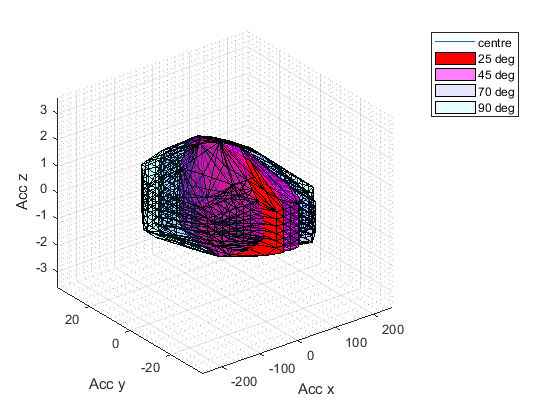

trisurf(bnd,alpha_x_s(row90),alpha_y_s(col90),alpha_z_s(page90),'Facecolor','cyan','FaceAlpha',0.1)


xlim([-lim1*1.2,lim1*1.2])
ylim([-lim2*1.2,lim2*1.2])
%axis equal
zlim([-lim3*1.2,lim3*1.2])
set(gca,'fontsize',10)
grid minor
grid on
legend('centre','25 deg','45 deg','70 deg','90 deg')
ylabel('Acc y')
xlabel('Acc x')
zlabel('Acc z')